# Average Number of Events per Decade

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

avgEventsPerDecade = [  74.2 83.8 99.2 159;
                        29 34 31.2 45];
grps = ["All Events" "US Events"];
labs = ["1800s" "First half of 1900s" "Second half of 1900s" "2000s"];
numEvents = [89; 82; 84; 61; 71; 110; 93; 104; 95; 94; 93; 110; 152; 19];
avgEventsPerDecade

avgEventsPerDecade =    74.2000   83.8000   99.2000  159.0000
   29.0000   34.0000   31.2000   45.0000


## Task 1

In a live script, you often don't need to think about the figure object unless you want to set certain properties, like background color.  

Use the `figure` command above your plotting code to create a figure handle.

`fig` `=` `figure`

f = figure

f =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


Create the bar plot.

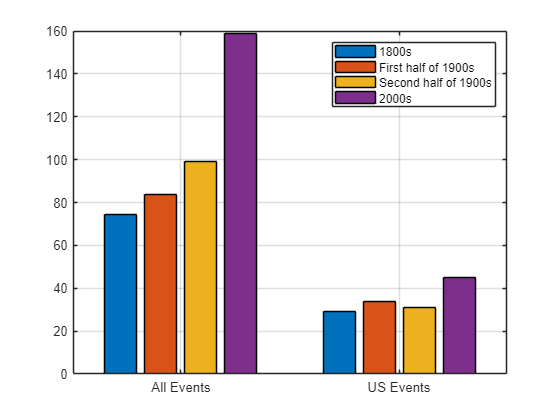

bar(avgEventsPerDecade) 
legend(labs)
xticklabels(grps)
grid on

## Task 2

You can change the background color using the `Color` property of a figure by setting it to a vector of red, green, and blue values between 0 and 1.

`fig.Color` `=` `[``r` `g` `b``]`

The default color is white, which is represented by `[``1` `1` `1``]`.

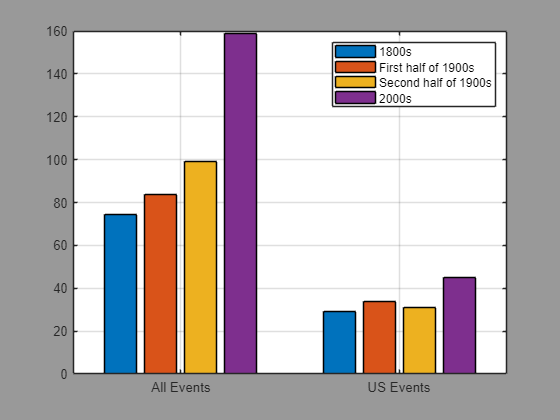

f.Color = [1 1 1]*.6;

## Task 3

Notice that the background changed *for all the subsequent figures*.  That is because MATLAB reuses the figure object in a live script.  If you don't want to reuse figure properties you previously defined, you can create a new figure.

`figure`

If you aren't going to modify the figure object and only need a new figure with default properties, then you do not need to assign it to an output.

figure

Create a stacked bar plot.

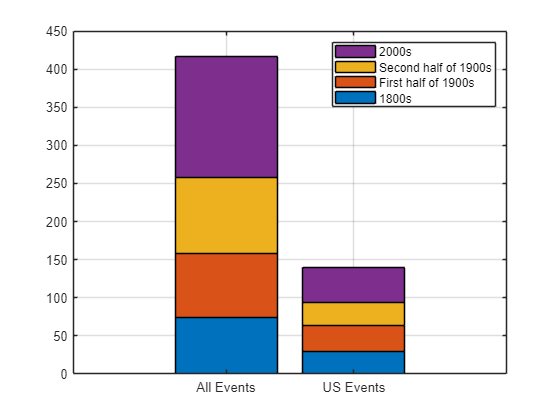

bar(avgEventsPerDecade, "stacked") 
legend(labs)
xticklabels(grps)
grid on